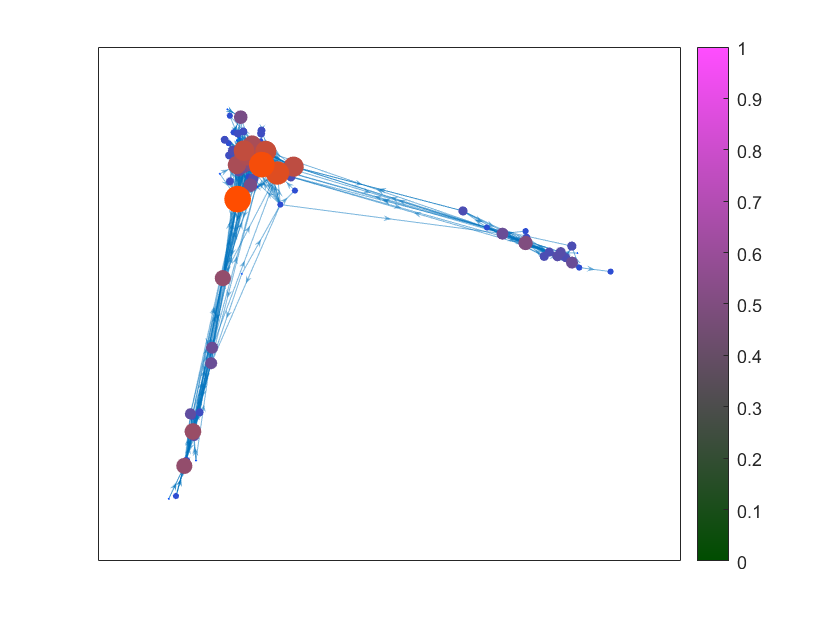

inp = readtable("g_edges.csv");
all_names = [inp.Source; inp.Target];
all_names = unique(all_names);

s_1 = inp.Source'; s_1 = string(s_1);
t_2 = inp.Target'; t_2 = string(t_2);


s_graph = zeros(1,length(s_1));
t_graph = zeros(1,length(t_2));
for i = 1:length(s_1)
    s_graph(i) = find(all_names==s_1(i));
    t_graph(i) = find(all_names==t_2(i));
end

Graph = digraph(s_graph,t_graph,(double(inp.Weight))');
deg_gr = indegree(Graph);
size_v = 2.*sqrt(deg_gr-min(deg_gr))+0.2;

colour = zeros(length(all_names),3);
for i=1:length(all_names)
    col = size_v(i)/max(size_v);
    colour(i,1) = col;
    colour(i,2) = 0.3;
    colour(i,3) = 1-col;
end

plot(Graph,'MarkerSize',size_v,'NodeColor',colour);
xlim([-2.48 5.69]);
ylim([-5.52 2.28]);
colormap([linspace(0,1,256);0.3*ones(1,256);linspace(0,1,256)]');
colorbar;


top = sort(deg_gr,'descend');
top_lim = top(6);
disp(flip(all_names(deg_gr>top_lim)));

    {'TYRION'}
    {'SANSA' }
    {'ROBERT'}
    {'ROBB'  }
    {'NED'   }




for i=shortestpath(Graph,find(all_names=="NED"),find(all_names=="TYRION"))
    disp(all_names(i))
end

    {'NED'}

    {'PYP'}

    {'TYRION'}

